# 実践ロバスト制御　第3章演習問題

clear; close all; clc;

## 問題1

**実制御対象**$\tilde{P}$**およびノミナルモデル**$P$**の伝達関数が次式で与えられるとき、乗法的摂動**$\Delta_m$**と加法的摂動**$\Delta_a$**を計算せよ。**


$$\tilde{P} = \frac{1}{(0.01s+1)(s+1)}\text{、} P = \frac{1}{s+1}$$


s = tf("s");
P = 1/((0.01*s+1)*(s+1));
Pn = 1/(s+1);
Dm = zpk(minreal((P-Pn)/Pn))

Dm =
 
    - s
  -------
  (s+100)
 
連続時間零点/極/ゲイン モデルです。



Da = zpk(minreal(P-Pn))

Da =
 
       - s
  -------------
  (s+100) (s+1)
 
連続時間零点/極/ゲイン モデルです。



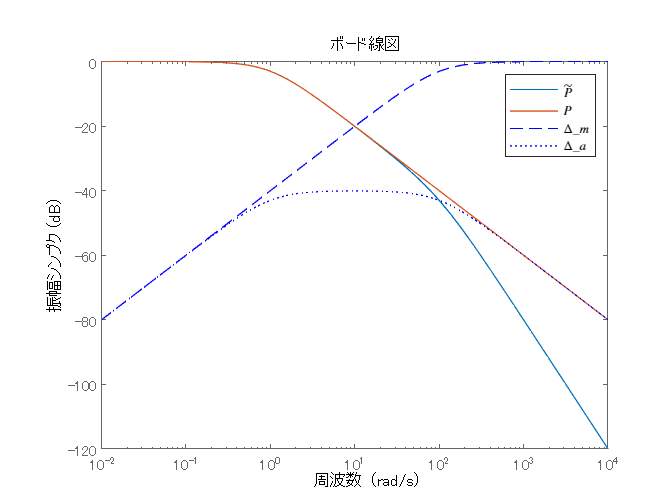

figure;
bodemag(P,Pn,Dm,"--",Da,":");
legend(["$\tilde{P}$","$P$","$\Delta_m$","$\Delta_a$"],"Interpreter","latex");

## 問題2

**ノミナルモデル**$P=1/(10s+1)$**に対して、無駄時間が変動するモデル集合**$\tilde{P}$**を次式で定義する。このとき、乗法的摂動を覆う重み関数**$W$**を決めよ。**


$$\tilde{P}=\lbrace Pe^{-\tau_ds}:\tau_d\in[0,\:0.1]\rbrace$$


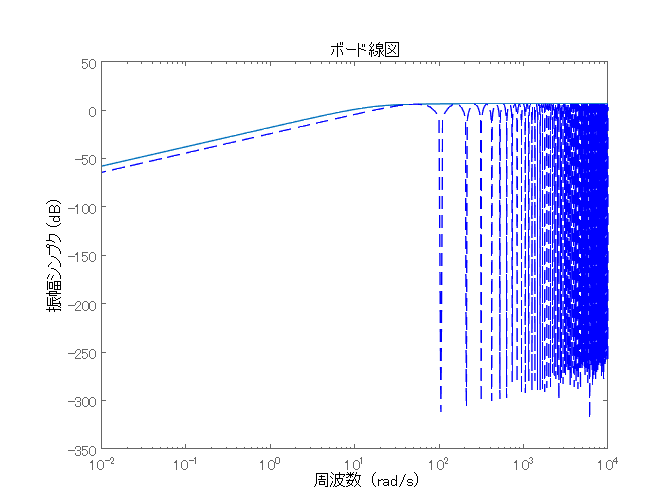

tau_d = 0.06;
s = tf("s");
Pn = 1/(10*s+1);
P = Pn*exp(-tau_d*s);
Dm = (P-Pn)/Pn;
W = 2.1*s/(s+1/tau_d); % ref:J.C. Doyle, B.A. Francis, and A.R. Tannenbaum (藤井隆雄 監訳):フィードバック制御の理論 : ロバスト制御の基礎理論, コロナ社(1996)
figure;
bodemag(W,Dm,"--");

## 問題3

**ノミナルモデル**$P$**および既知の伝達関数**$W\in \mathcal{RH}^{2}$**に対して、モデル集合**$\tilde{P}$**を次式で定義する。**


$$\tilde{P}=\left\lbrace \frac{P}{1+\Delta W}:\|\Delta\|_{\infty}\le1, \Delta \in \mathcal{RH}^{\infty}\right\rbrace$$


**このとき、スモールゲイン定理を用いて、すべての**$\tilde{P}$**に対して、閉ループ系がロバスト安定となるための必要十分条件を導け。**

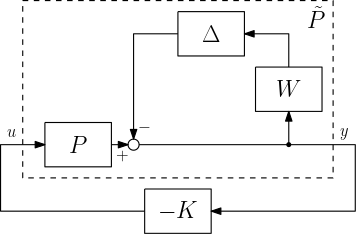

$\tilde{P}$に対する閉ループ系は上図となるため、これを等価変換することで下図となる。（$S=(1+PK)^{-1}$）

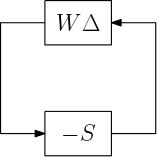

従って、スモールゲイン定理を適用することで次式を得られる。


$$\left\|WS\right\|_\infty < 1$$


## 問題4

**前問題3において、モデル集合**$\tilde{P}$**を次式とした場合の、ロバスト安定化条件を導け。**


$$\tilde{P}=\left\lbrace \frac{P}{1+\Delta WP}:\|\Delta\|_{\infty}\le1, \Delta \in \mathcal{RH}^{\infty}\right\rbrace$$


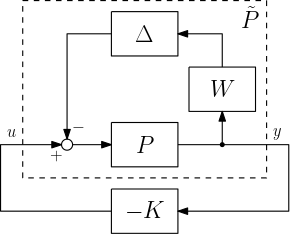

$\tilde{P}$に対する閉ループ系は上図となるため、これを等価変換することで下図となる。（$S=(1+PK)^{-1}$）

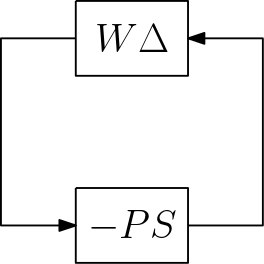

従って、スモールゲイン定理を適用することで次式を得られる。


$$\left\|WPS\right\|_\infty < 1$$


## 問題5

**モデル集合**


$$\tilde{P}=\left\lbrace \frac{1}{s+a}:a\in [\underline{a},\:\bar{a}]\right\rbrace$$

$$\qquad\text{式(3.16)}$$


s = tf("s");
amax = 2;
amin = 1;
a0 = (amax+amin)/2;
a = ureal("a",a0,"Range",[amin,amax]);
P = 1/(s+a);

**と制御器**$K$**で構成される閉ループ系に対して、この系を内部安定化するゲイン制御器**$K=k_p$**を設計する問題を考える。つぎの各問いに答えよ。**

**1. 閉ループ系が内部安定となるとき、**$k_p$**が満たすべき条件を求めよ。**

全ての$a\in[\underline{a},\overline{a}]$に対して閉ループ極が負となればよいので、


$$k_p>-\underline{a}$$


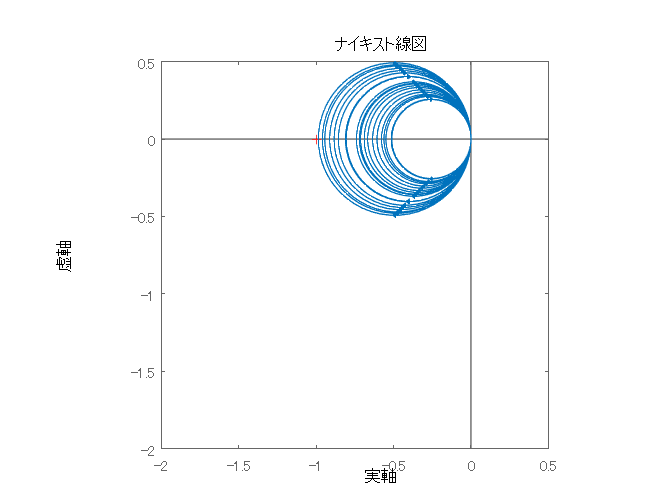

kp = -1;
L = P*kp;
figure;
op = nyquistoptions("cstprefs");
op.ShowFullContour = "off";
nyquist(L);
xlim([-2, 0.5]); ylim([-2, 0.5]);
pbaspect([1 1 1]);

**2. ノミナルモデルを**$P=1/(s+a_0)$**と定める。ただし、**$a_0=(\underline{a}+\overline{a})/2$**とする。このとき、式(3.16)は**$W=(\overline{a}-\underline{a})/2$**に対して**


$$\tilde{P}=\left\lbrace \frac{P}{1+\Delta WP}:|\Delta|\le1, \Delta \in \mathcal{R}\right\rbrace$$


**と表現できることを示せ。**

$\Delta=(a-a_0)/W$とおくと$|\Delta|\le1$および


$$\tilde{P}=\frac{1}{s+a}$$


となる。

**3. 上記2.で定義したモデル集合において、**$\Delta$**を実数ではなく、**$\|\Delta\|_\infty \le1$**を満たす**$\Delta \in \mathcal{RH}^{\infty}$**と仮定する。このように定義し直した**$\Delta$**に対して、閉ループ系が内部安定となるための**$k_p$**の条件を求めよ。**

問題4を使うと、


$$\left\|WPS\right\|_\infty =
\left\|\frac{W}{s+a_0+k_p}\right\|_\infty<1$$


が成り立てばよく、これは$W/(a_o+k_p)<1$と等価である。閉ループの安定性も考慮しつつ上式を解き、


$$k_p>-\underline{a}$$
